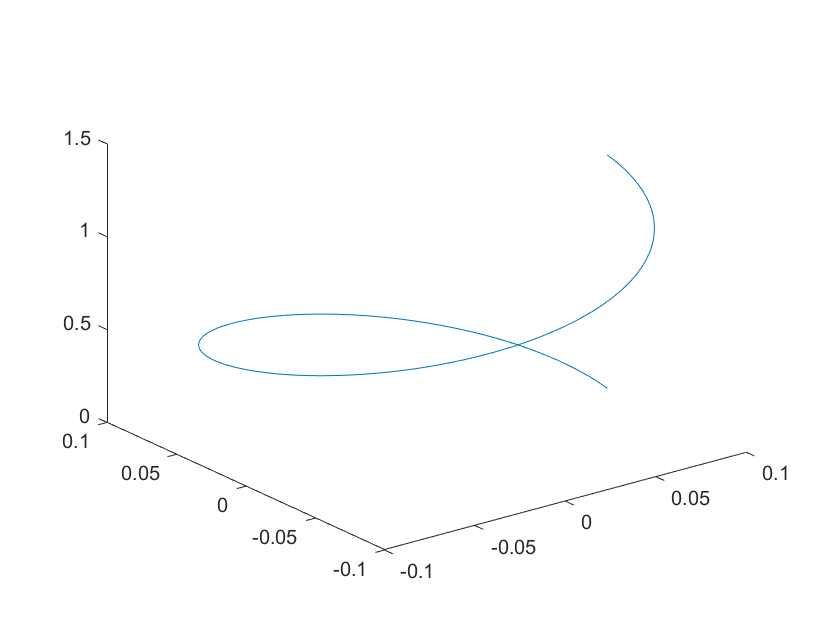

clear
clc
u=linspace(0,2*pi,1000)';
%for i=1:10
a=0.1;
b=0.2;
x_=a*cos(u);
y_=a*sin(u);
z_=b*u;
r=2*[x_,y_,z_];
figure,plot3(x_,y_,z_)
hold on

drawnow

drdu = diff(r)./diff(u) % compute an approximation to the derivative

drdu =    -0.0006    0.2000    0.4000
   -0.0019    0.2000    0.4000
   -0.0031    0.2000    0.4000
   -0.0044    0.2000    0.4000
   -0.0057    0.1999    0.4000
   -0.0069    0.1999    0.4000
   -0.0082    0.1998    0.4000
   -0.0094    0.1998    0.4000
   -0.0107    0.1997    0.4000
   -0.0119    0.1996    0.4000


That = drdu./sqrt(sum(drdu.^2,2)) % compute the unit tangent vector

That =    -0.0014    0.4472    0.8944
   -0.0042    0.4472    0.8944
   -0.0070    0.4472    0.8944
   -0.0098    0.4471    0.8944
   -0.0127    0.4470    0.8944
   -0.0155    0.4469    0.8944
   -0.0183    0.4468    0.8944
   -0.0211    0.4467    0.8944
   -0.0239    0.4466    0.8944
   -0.0267    0.4464    0.8944


N = diff(That)./diff(u(1:end-1)) % compute the normal vector

N =    -0.4472   -0.0028         0
   -0.4472   -0.0056    0.0000
   -0.4471   -0.0084         0
   -0.4471   -0.0112   -0.0000
   -0.4470   -0.0141   -0.0000
   -0.4469   -0.0169    0.0000
   -0.4468   -0.0197   -0.0000
   -0.4466   -0.0225    0.0000
   -0.4465   -0.0253   -0.0000
   -0.4463   -0.0281    0.0000


Nhat = N./sqrt(sum(diff(drdu).^2,2)) % make it a unit normal

Nhat =  -355.5185   -2.2361         0
 -355.4974   -4.4720    0.0000
 -355.4622   -6.7078         0
 -355.4130   -8.9433   -0.0000
 -355.3497  -11.1785   -0.0000
 -355.2724  -13.4132    0.0000
 -355.1810  -15.6474   -0.0000
 -355.0756  -17.8810    0.0000
 -354.9561  -20.1139   -0.0000
 -354.8226  -22.3459    0.0000




for i = 1:length(u)-2 % animate the unit tangent vector and unit normal vector
    clf
    hold on
    plot(r(:,1),r(:,2)) % plot the entire path
    quiver(r(i,1),r(i,2),That(i,1),That(i,2)) % plot That
    quiver(r(i,1),r(i,2),Nhat(i,1),Nhat(i,2)) % plot Nhat
    axis equal % equal axis so that it looks lke a circle
    axis([-0.5 0.5 -0.5 0.5]) % plot domain large enough to see what is going on
    drawnow % force the plotting otherwise it will plot everything at once
end
